# Polinomios de interpolación en el análisis de temperatura

TNov = readmatrix('noviembre.csv','Range','C12:C730')';
tNov = (0:1:length(TNov)-1); 

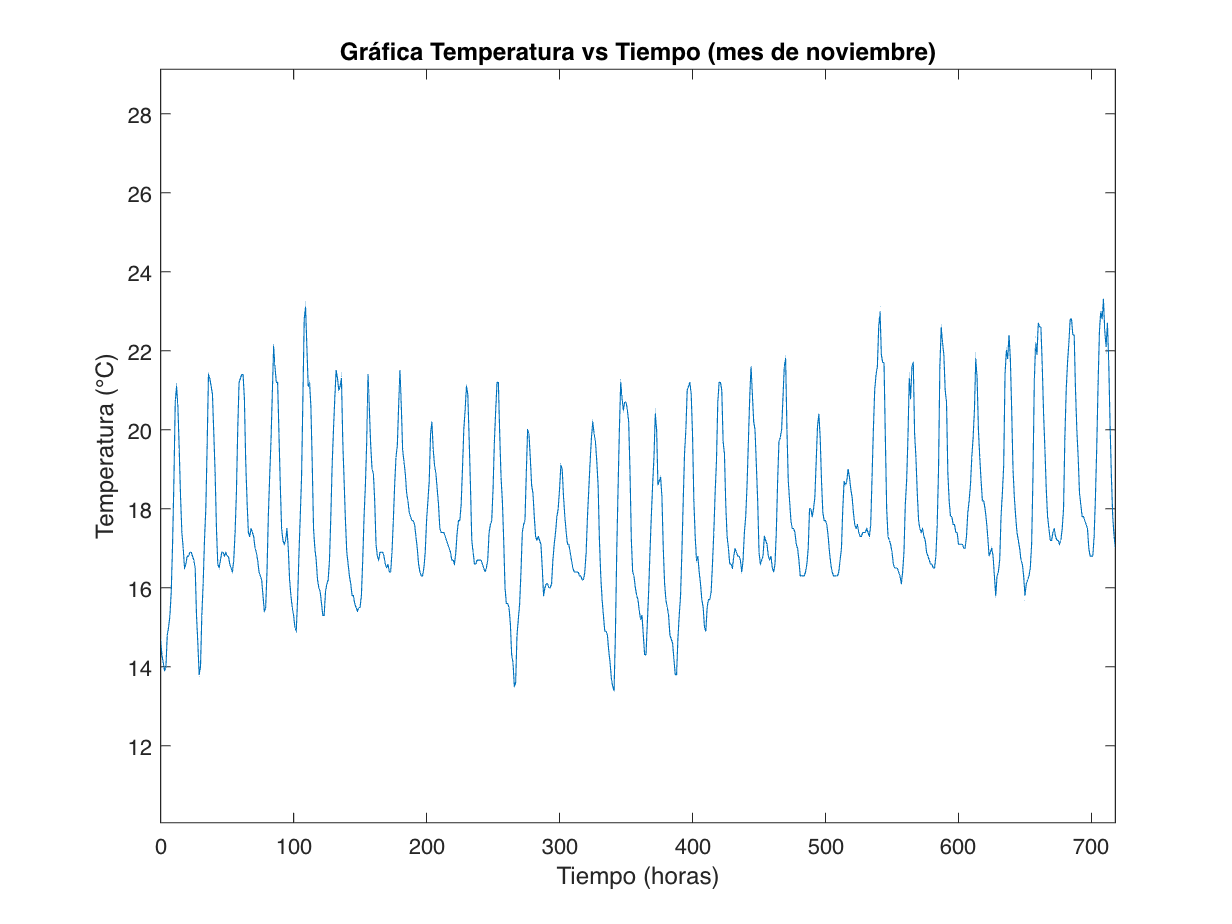

GraficaGeneral(TNov, tNov); hold off;

opcion = input('¿Usted tiene conocimiento del proyecto? Sí/No: ', 's');

if strcmp(opcion, 'Sí')
    hora = input("Ingresa la hora del día a analizar (0-23): ");
    grado = input("Ingresa el grado del polinomio aproximante: ");
else
    hora = 12;
    grado = 4;
    fprintf('Hora por defecto: %d\n', hora)
    fprintf('Grado de polinomio de mínimos cuadrados por defecto: %d\n', grado)
end

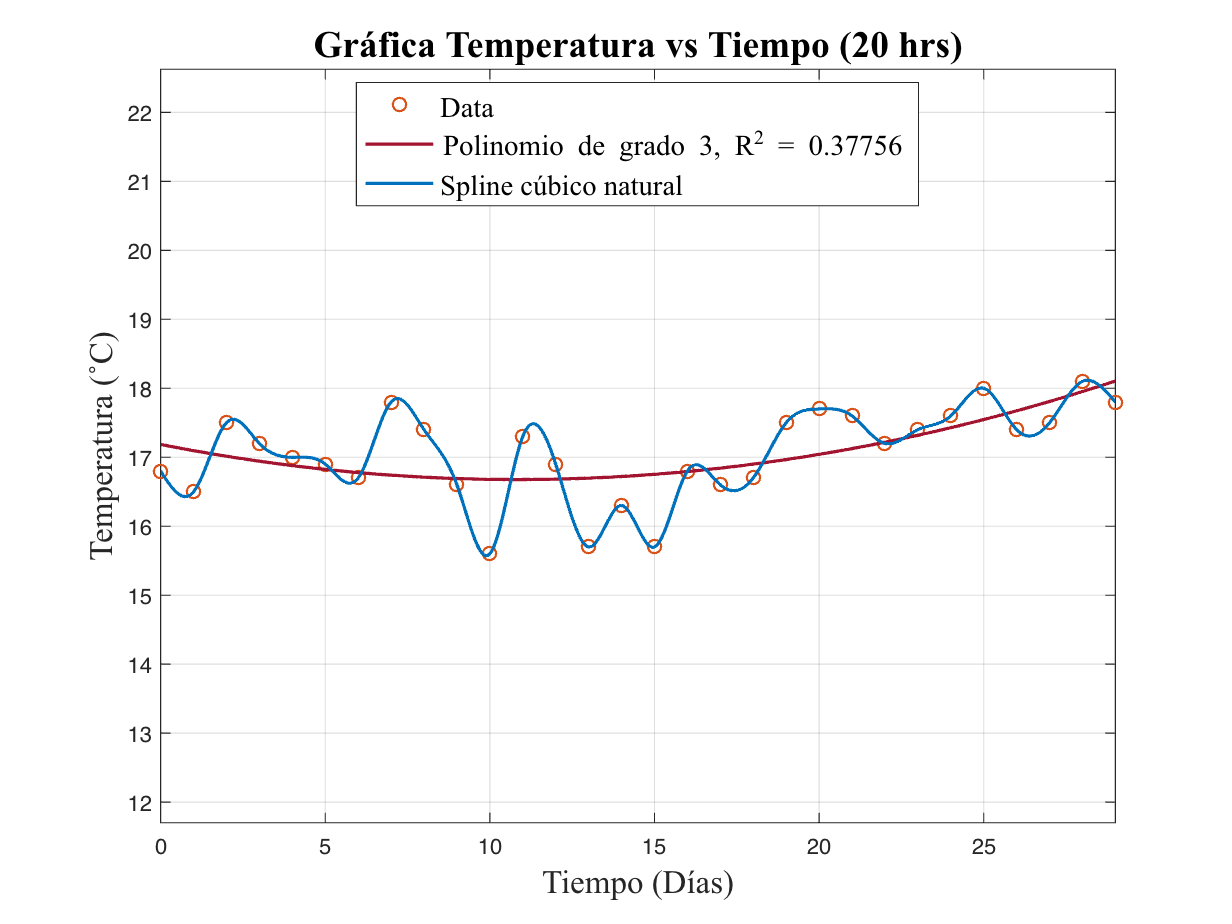

[tNovHora, TNovHora, Sx, P] = GraficaSpline(TNov, hora+1, grado);
hold off

### 
$$\textrm{Polinomio}\;\textrm{de}\;\textrm{Mínimos}\;\textrm{Cuadrados}:$$



$$P_4 \left(t\right)=\;$$


syms t

disp(poly2sym(round(vpa(P, 2), 8), t))

$$-0.00000075\,t^{3}+0.0043618\,t^{2}-0.09415021\,t+17.18606305$$

### 
$$\mathrm{Spline}\;\mathrm{Cúbico}\;\mathrm{Natural}:$$


#### 
$$S_i \left(t\right)={a\left(t-t_i \right)}^3 +{b\left(t-t_i \right)}^2 +c\left(t-t_i \right)+d\;\;\forall \;\;\;\;i=0,1,\ldotp \ldotp \ldotp ,N-1$$


disp(Sx)

    i     (t-t[i])        a           b            c         d       [t(i), t(i+1)]  
    __    ________    _________    ________    _________    ____    _________________

     0    "(t-0)"       0.44231           0     -0.74231    16.8    "si t ∈ [0, 1]"  
     1    "(t-1)"      -0.91157      1.3269      0.58463    16.5    "si t ∈ [1, 2]"  
     2    "(t-2)"       0.60395     -1.4078      0.50381    17.5    "si t ∈ [2, 3]"  
     3    "(t-3)"      -0.10424      0.4041     -0.49986    17.2    "si t ∈ [3, 4]"  
     4    "(t-4)"      -0.18699    0.091376    -0.004384      17    "si t ∈ [4, 5]"  
     5    "(t-5)"       0.65221     -0.4696     -0.38261    16.9    "si t ∈ [5, 6]"  
     6    "(t-6)"       -1.0218       1.487      0.63482    16.7    "si t

Graficamos el polinomio interpolante de Newton:

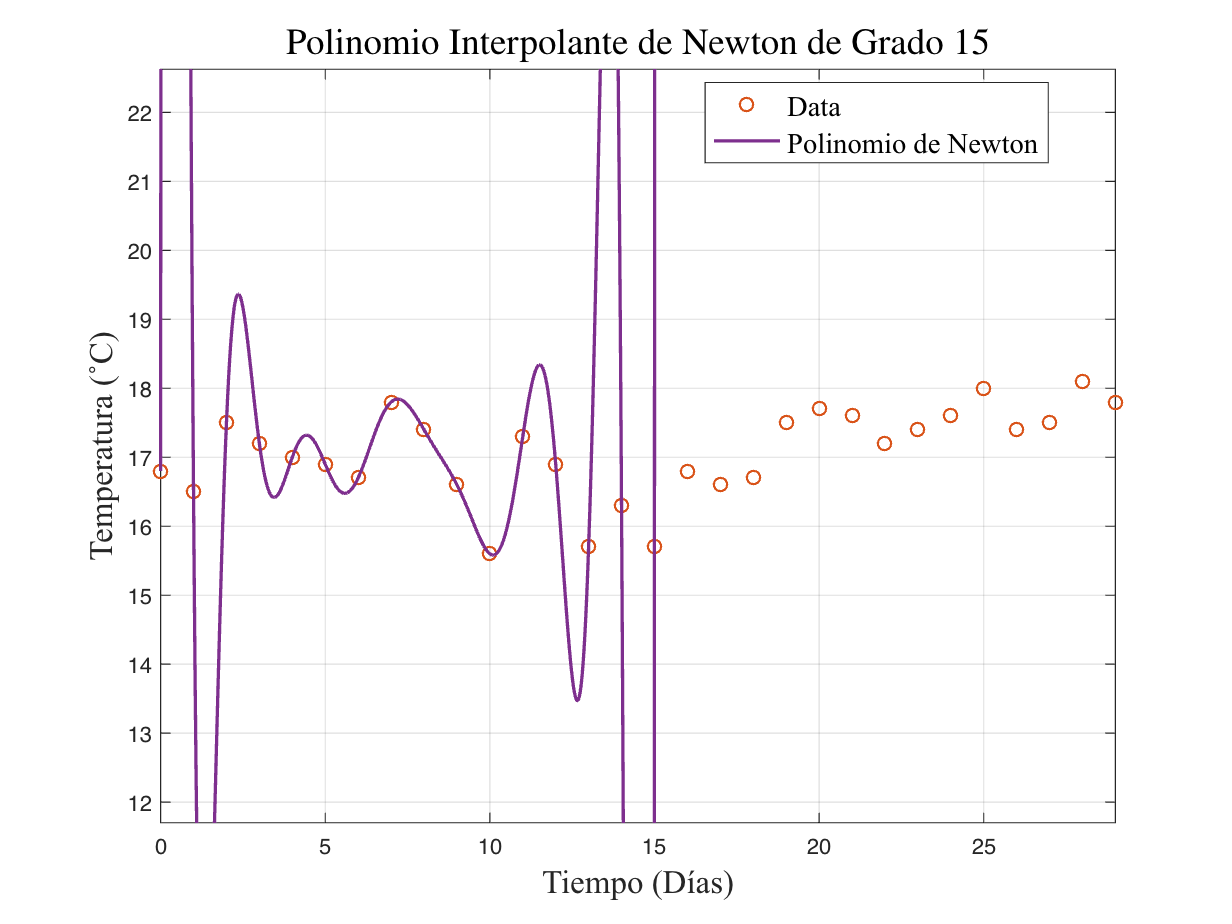

GraficaNewton(tNovHora, TNovHora, ceil(length(tNovHora)/2));

Gráfica de aproximación de Temperatura para los primeros días de diciembre:

TDic = readmatrix('diciembre.csv','Range','C12:C263')';
TDicHora = TDic((hora+1):24:end);
[~, n] = size(TDicHora);

fprintf("Cantidad de Temperaturas reales de diciembre disponibles para las %d:00 hrs: %d", hora, n)

Cantidad de Temperaturas reales de diciembre disponibles para las 20:00 hrs: 10

while true
    cant_dias = input("Ingrese la cantidad [c] de días de diciembre para estimar (c<=" +int2str(n) + "): ");
    if cant_dias <= n
        break
    end
end

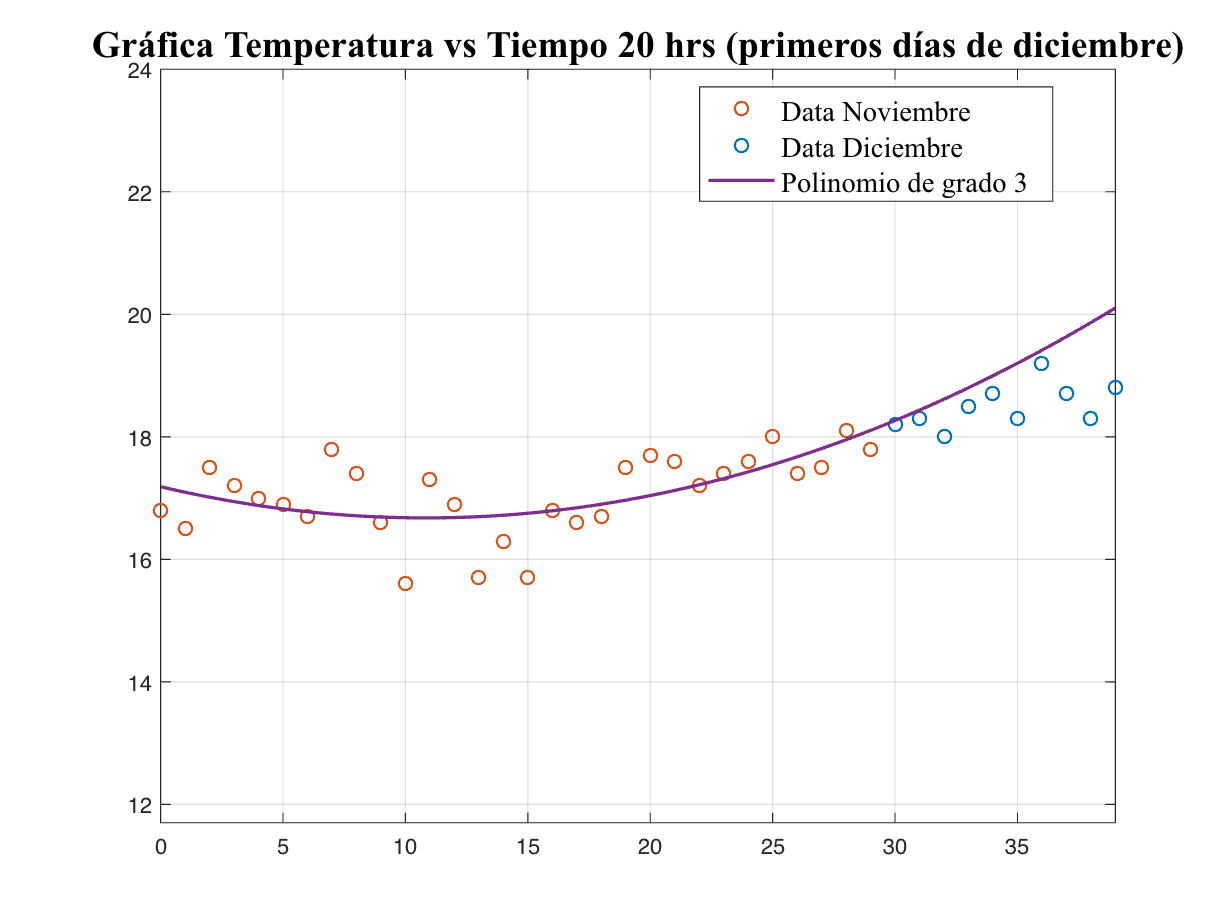

GraficaConDiciembre(TNovHora, TDicHora(1, 1:cant_dias), hora+1, P, grado, cant_dias);

Taprox = polyval(P, (30:1:(29+cant_dias)));
Treal = TDicHora(1:cant_dias);
Error_absoluto = abs(Treal - Taprox);
disp("Error absoluto de las aproximaciones realizadas para el mes de Diciembre en orden diario"); disp(Error_absoluto);

Error absoluto de las aproximaciones realizadas para el mes de Diciembre en orden diario
    0.0670    0.1368    0.6152    0.3022    0.2978    0.9019    0.2146    0.9359    1.5657    1.3041



fprintf("Norma euclidiana (2) del error absoluto de las aproximaciones de Temperatura: %f", norm(Error_absoluto, 2))

Norma euclidiana (2) del error absoluto de las aproximaciones de Temperatura: 2.543407

Error_relativo = Error_absoluto./Treal;
disp("Error relativo de las aproximaciones realizadas para el mes de Diciembre en orden diario"); disp(Error_relativo);

Error relativo de las aproximaciones realizadas para el mes de Diciembre en orden diario
    0.0037    0.0075    0.0342    0.0163    0.0159    0.0493    0.0112    0.0500    0.0856    0.0694



fprintf("Norma euclidiana (2) del error relativo de las aproximaciones de Temperatura: %f", norm(Error_relativo, 2))

Norma euclidiana (2) del error relativo de las aproximaciones de Temperatura: 0.137651